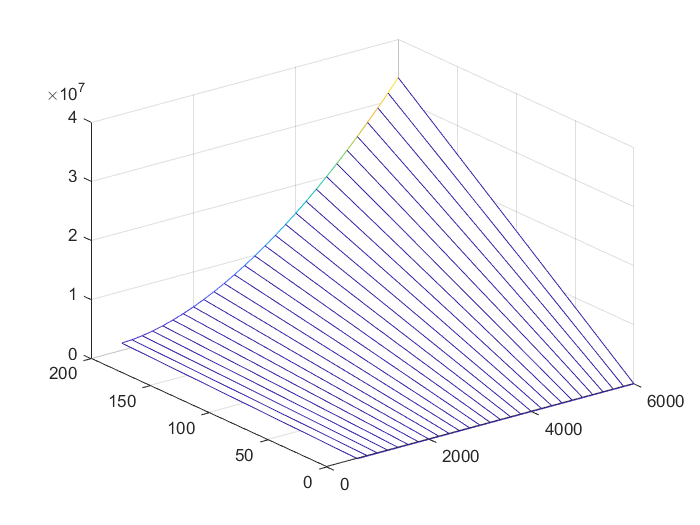

Drehzahl_max = 6000;    %Maximale Drehzahl [1/min]
Drehmoment_max = 200;   %Maximales Drehmoment [Nm]
Leistung_max = 120000;  %Maximale Leistung [W]
Drehzahl = [];
%Drehzahlvektor mit inkrement = 200 [1/min]
for i_Drehzahlband = 600:200:Drehzahl_max
    Drehzahl(:,end+1) = i_Drehzahlband;
end
%Willanslinie 
Drehmoment = [0 Drehmoment_max];
l_Drehzahl = length(Drehzahl);
Verbrauch = [];
for i_Verbrauch = 1:l_Drehzahl
b_abs = (1237000/200)*Drehmoment_max + (Drehzahl(i_Verbrauch)-600)^1.8*6.164;
Verbrauch(1,i_Verbrauch) = 0;
Verbrauch(2,i_Verbrauch) = b_abs;
end
figure
mesh(Drehzahl, Drehmoment, Verbrauch)

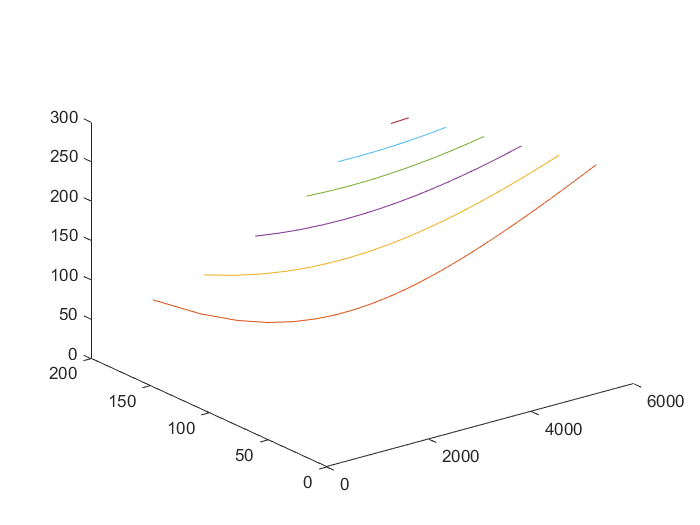

%Kurven gleicher Leistung
i_schrittzaehler = 1;
figure
plot3(1,1,1)   
hold on
for i_Leistung = 20000:20000:Leistung_max   %Leistung P[kW] in 20er steps
   Temp_Drehzahl = [];
   Temp_Drehmoment = [];
   Temp_Verbrauch = [];
    for i_Drehzahlgerade = 1:l_Drehzahl   %jede Drehzahlgerade 
        %Stützstellen Willanslinie        
        x_maxNm = Verbrauch(2,i_Drehzahlgerade)/Drehmoment_max;
        n_muschel = Drehzahl(i_Drehzahlgerade);
        %Gesuchtes Drehmoment
        M_muschel = (i_Leistung)/(n_muschel*(pi/30));
        %Geradengleichung aufstellen
        babs_muschel = M_muschel * x_maxNm;        
            if M_muschel <= Drehmoment_max    
               Temp_Drehzahl(:, end+1) = n_muschel;             %aktuelle Drehzahl
               Temp_Drehmoment(:, end+1) = M_muschel;             %aktuelles Moment
               Temp_Verbrauch(:, end+1) = babs_muschel/(i_Leistung); %Spezifischer Verbrauch
            end       
    end
     Temp_Verbrauch = Temp_Verbrauch(1,:) - i_schrittzaehler*10;
     X_Drehzahl{i_schrittzaehler} = Temp_Drehzahl;
     Y_Drehmoment{i_schrittzaehler} = Temp_Drehmoment;
     Z_Verbrauch{i_schrittzaehler} = Temp_Verbrauch;
     plot3(X_Drehzahl{i_schrittzaehler}, Y_Drehmoment{i_schrittzaehler},Z_Verbrauch{i_schrittzaehler});     
     i_schrittzaehler = i_schrittzaehler+1;        
end

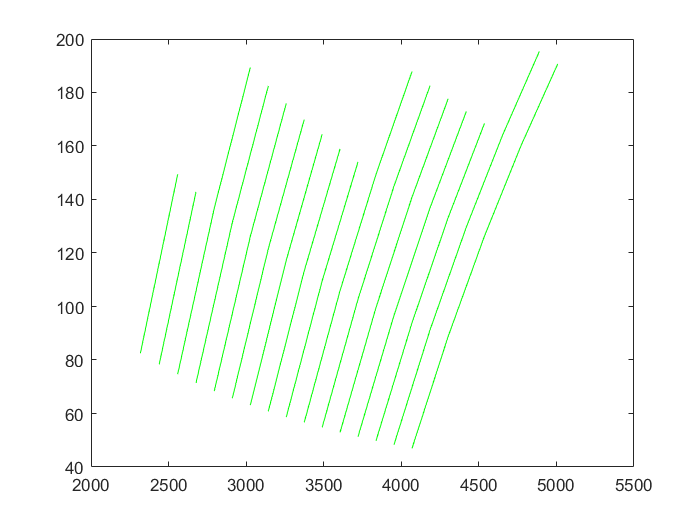

%{
%Künstlichen Offset der Verbrauchskurven erstellen
offset = length(Z_Verbrauch)*10-10;
l_Verbrauch = length(Z_Verbrauch)-1;
for i_offset = 1:l_Verbrauch
    Z_Verbrauch{1,i_offset} = Z_Verbrauch{1,i_offset} - offset;
    offset = offset + 10;
    
end
%}
%Schnittpunkte von Drehzahl und Drehmoment bei gleichem Verbrauch
%2D Darstellung Drehzahl-Verbrauch & Moment-Verbrauch
%jeweiliger SP bei spez. Verbrauch für v_spez_x[g/kWh](Drehzahl/Moment)
i_schrittzaehler = 1;
for b_spez = 100:5:200   
    A_Drehzahl = [];
    A_Drehmoment = [];
    for i_Schnittpunkte = 1:6
        %Schnittpunkt Verbrauch-Drehzahl
        l_Drehzahl_Schnittpunkt = length(X_Drehzahl{i_Schnittpunkte});
        X_I = X_Drehzahl{i_Schnittpunkte};
        Z_I = Z_Verbrauch{i_Schnittpunkte};
        for i_Schnittpunkt_nv = 1:(l_Drehzahl_Schnittpunkt-1)
            n1 = X_I(i_Schnittpunkt_nv);
            v1 = Z_I(i_Schnittpunkt_nv);
            n2 = X_I(i_Schnittpunkt_nv+1);
            v2 = Z_I(i_Schnittpunkt_nv+1);
            m_bspez = (v2 - v1)/(n2 - n1);   %Steigung Gerade
            n_gesucht = (b_spez-v1+m_bspez*n1)/m_bspez;
            if n_gesucht >= n1 && n_gesucht <= n2
            A_Drehzahl(:, end+1) = n_gesucht;            
            end     
        end    
        %Schnittpunkt Moment Verbrauch 
        Y_I = Y_Drehmoment{i_Schnittpunkte};
        for i_Schnittpunkt_mv = 1:(l_Drehzahl_Schnittpunkt-1)
            m1 = Y_I(i_Schnittpunkt_mv);
            v1 = Z_I(i_Schnittpunkt_mv);
            m2 = Y_I(i_Schnittpunkt_mv+1);
            v2 = Z_I(i_Schnittpunkt_mv+1);
            M_bspez = (v2 - v1)/(m2 - m1);   %Steigung Gerade
            m_gesucht = (b_spez-v1+M_bspez*m1)/M_bspez;
            if m_gesucht >= m2 && m_gesucht <= m1
                A_Drehmoment(:, end+1) = m_gesucht;            
            end           
        end       
    end
    X_Verbrauch{i_schrittzaehler} = A_Drehzahl;
    Y_Verbrauch{i_schrittzaehler} = A_Drehmoment;     
    i_schrittzaehler = i_schrittzaehler + 1;
end
figure
for xxx = 1:16
    X1 = X_Verbrauch{xxx};
    Y1 = Y_Verbrauch{xxx};
    plot(X1,Y1, 'g-')
    hold on
    
end